# Example 6.12: Fourier Transform of a Periodic Signal

Note: this script reproduces Example 6.12 (Section 6.3.2) of **Statistics for Chemical Engineers**: the frequency spectrum of a signal made of two sine waves. Victor Z UW-Madison, 2020 illustrate fourier transform

clc;  clear all; close all hidden; format short 


L = 500;                                  % length of signal
Fs= 1000;                                 % Hz (sampling frequency)
T = 1/Fs;                                 % sec (sampling period)
t = (0:L-1)*T;                            % time vector
om = Fs*(0:(L/2))/L;                      % frequency vector

## Signal

get signal

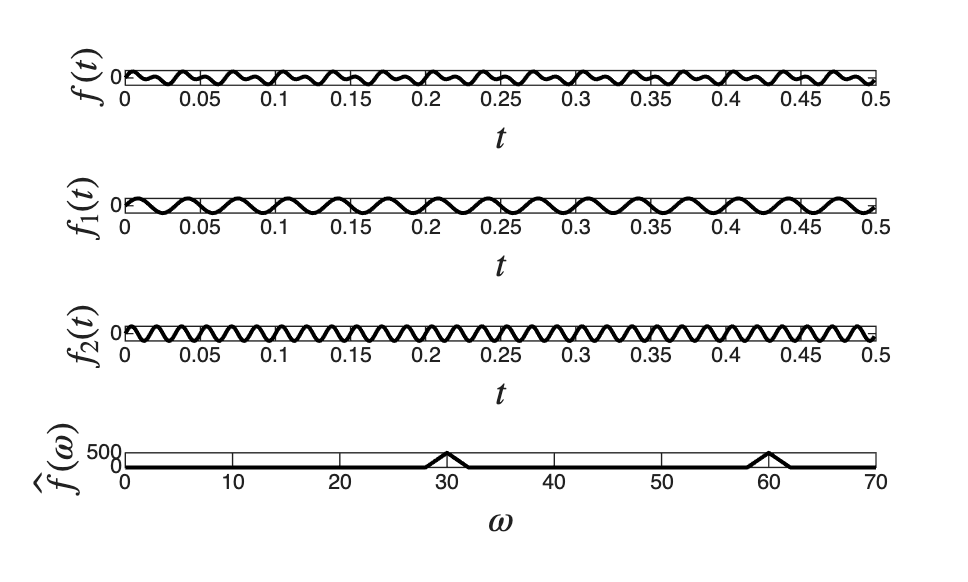

f1 = sin(2*pi*30*t);                      % low frequency          
f2 = sin(2*pi*60*t);                      % high frequency                 
f = f1+f2;                                % signal
fh = fft(f);                              % compute DFT 
m = abs(fh);                              % magnitude
mf = m(1:L/2+1);                          % eliminate symmetry
mf(2:end-1) = 2*mf(2:end-1);

% visualize signal
figure(3)
subplot(4,1,1)
plot(t,f,'black','LineWidth',1.5)
ylabel('$f(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)
subplot(4,1,2)
plot(t,f1,'black','LineWidth',1.5)
ylabel('$f_1(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)
subplot(4,1,3)
plot(t,f2,'black','LineWidth',1.5)
xlabel('$t$','Interpreter','Latex','FontSize',14)
ylabel('$f_2(t)$','Interpreter','Latex','FontSize',14)
subplot(4,1,4)
plot(om,mf,'black','LineWidth',1.5)
grid on
ylabel('$\hat{f}(\omega)$','Interpreter','Latex','FontSize',14)
xlabel('$\omega$','Interpreter','Latex','FontSize',14)
axis([0 70 0 max(mf)])
print -depsc ch6_sine_signal.eps

## Time and frequency domains

visualize signal in time and frequency domain

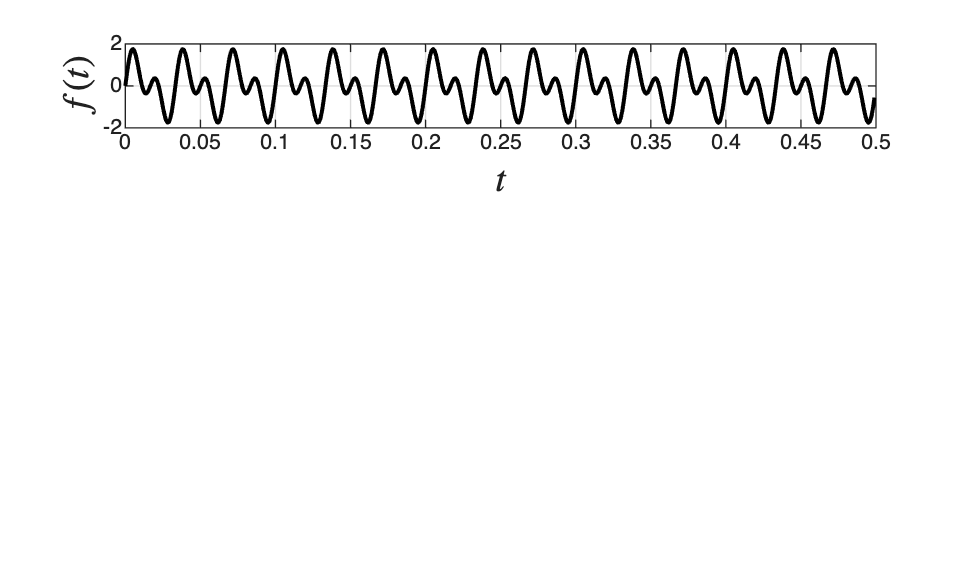

figure(1)
subplot(3,1,1)
plot(t,f,'black','LineWidth',1.5)
grid on
ylabel('$f(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)

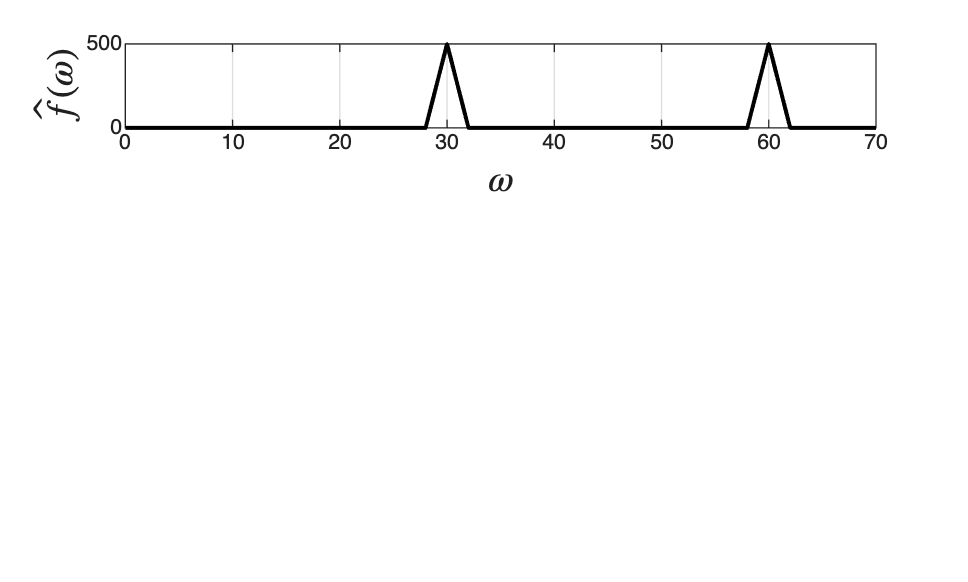


figure(2)
subplot(3,1,1)
plot(om,mf,'black','LineWidth',1.5)
grid on
ylabel('$\hat{f}(\omega)$','Interpreter','Latex','FontSize',14)
xlabel('$\omega$','Interpreter','Latex','FontSize',14)
axis([0 70 0 max(mf)])

## Filtering

get filter

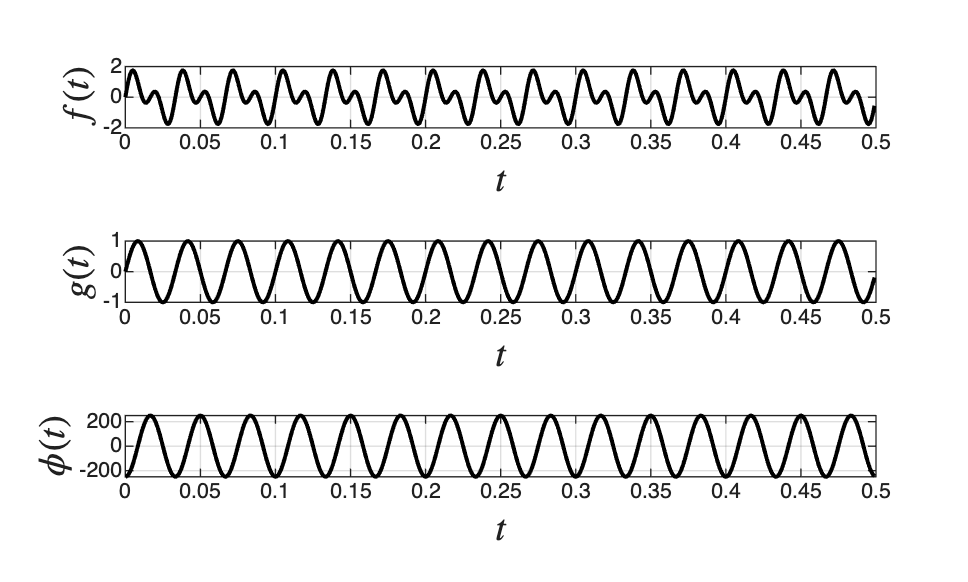

g = sin(2*pi*30*t);                       % signal
gh = fft(g);                              % compute DFT 
m  = abs(gh);                             % magnitude
mg = m(1:L/2+1);
mg(2:end-1) = 2*mg(2:end-1);

figure(1)
subplot(3,1,2)
plot(t,g,'black','LineWidth',1.5)
grid on
ylabel('$g(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)

figure(2)
subplot(3,1,2)
plot(om,mg,'black','LineWidth',1.5)
axis([0 70 0 max(mg)])
grid on
ylabel('$\hat{g}(\omega)$','Interpreter','Latex','FontSize',14)
xlabel('$\omega$','Interpreter','Latex','FontSize',14)


% do product of fft signals to obtain filtered signal

phih=fh.*gh;                               % signal in frequency domain
phi=ifft(phih);                            % signal in time domain  
m = abs(phih);                             % magnitude
mphi = m(1:L/2+1);
mphi(2:end-1) = 2*mphi(2:end-1);

figure(1)
subplot(3,1,3)
plot(t,phi,'black','LineWidth',1.5)
grid on
ylabel('$\phi(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)

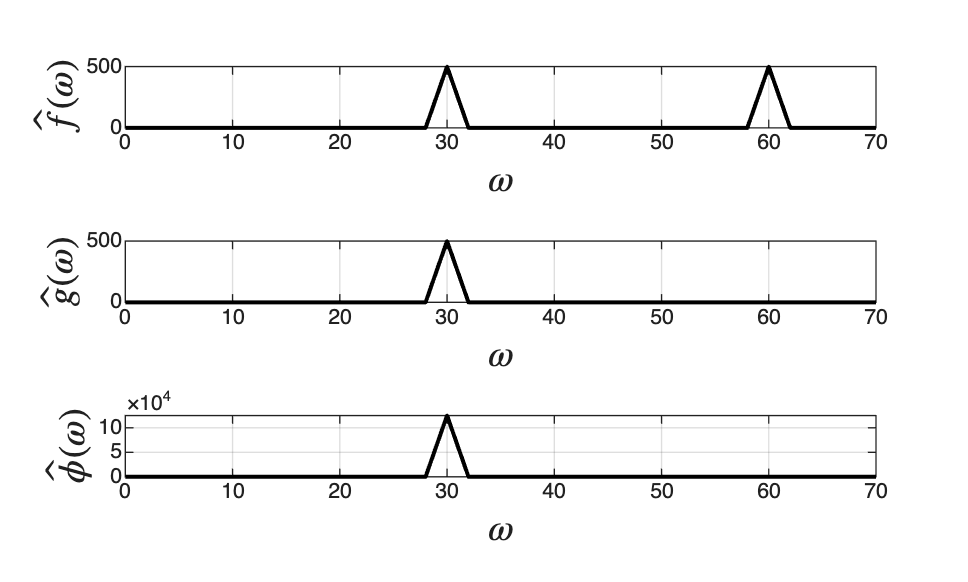


figure(2)
subplot(3,1,3)
plot(om,mphi,'black','LineWidth',1.5)
axis([0 70 0 max(mphi)])
grid on
ylabel('$\hat{\phi}(\omega)$','Interpreter','Latex','FontSize',14)
xlabel('$\omega$','Interpreter','Latex','FontSize',14)

## Note

As in the book, the Fourier transform reveals the two dominant frequencies of the signal (30 and 60).